# Create App

This example shows how to use the **Generate JavaScript using MATLAB Coder** add-on to create a basic web application with a user interface that runs entirely in a web browser.

## Set Up the App Project

1. In the MATLAB® current folder browser, navigate to a folder where you can create and store your app project and files. 

2. Create the app project by entering this code in MATLAB command line. Specify a name and the directory for your app.

proj = webcoder.setup.project("My New App","Directory",pwd);

This image shows the typical view of an app project.

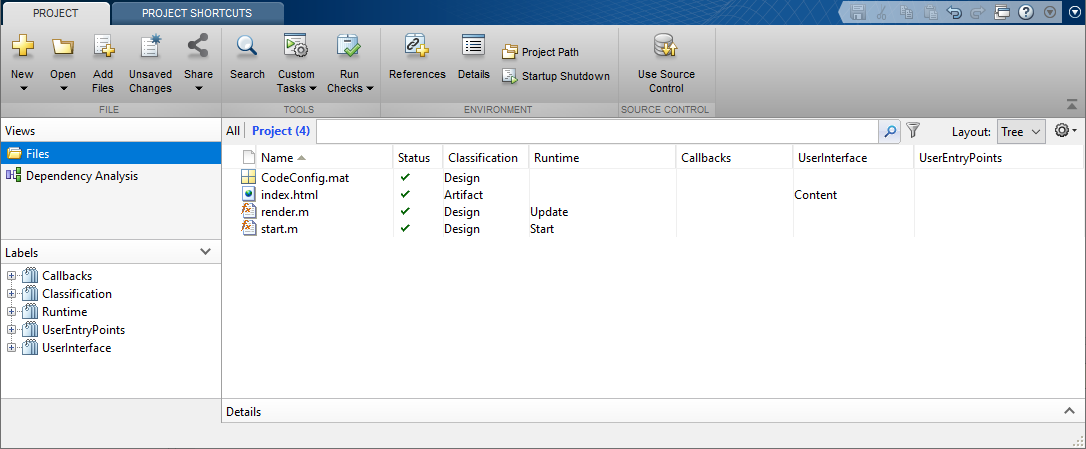

3. Open the `start.m` function file and update the function by adding a `webcoder.console.log` function call. You must use character arrays for successful code generation. The `start` function is called once when the app starts.

4. Similarly, open the `renderm` function file and update the function by adding a `webcoder.console.log` function call. The `render` function is called at a rate of 60 Hz and can be used to efficiently make updates to the user interface.

## Build the App

To build the app project, enter this code at the command prompt. The amount of time it take for the app to build depends on your host computer.

proj = openProject(pwd);
webcoder.build.project(proj);

The resulting app is the set of 4 files located in the `dist` folder.

## Run the App

From the MATLAB command line, you can launch the app in a local server. To create the server and launch the app in the `dist folder`, enter this code.

localServer = webcoder.utilities.DevelopmentServer("Directory",'dist',"Port",8000);
start(localServer);

Stop the server at any time using this command.

stop(localServer);

In a modern web browser, you can open the app by navigating to this IP address: [http://localhost:8000](http://localhost:8000). After the web page opens as a blank screen, open the browser developer tools by pressing **Ctrl+Shift+i**. The Console window displays the output of the s`tart` and r`ender` functions.

## See Also

- Create App with Callback

- Deploy App to Github Pages